# mAD tests

current_tile = "tile_4"

current_tile = "tile_4"

input_path = fullfile("G:/2021-03-14-mAD-comparison/");
img_path = fullfile(input_path, 'pi', sprintf("%s.tif", current_tile));
spot_path = fullfile(input_path, "max", current_tile, "goodPoints_max3d.mat");

current_dapi = new_LoadMultipageTiff(img_path, 'uint8', 'uint8', false);
load(spot_path);

spot_stack = get_spot_stack(current_dapi, tile_goodSpots, [2 2 1]);

file_name = sprintf("%s_spot.tif", current_tile)

file_name = "tile_4_spot.tif"

output_path = fullfile(input_path, "output", current_tile);
file_path = fullfile(output_path, file_name);

if exist(file_path, 'file') == 2
   delete(file_path);
end

for z=1:size(spot_stack, 3)        
    imwrite(spot_stack(:,:,z), file_path, 'writemode', 'append');        
end

current_tile = "tile_2"

current_tile = "tile_2"

input_path = fullfile("G:/2021-03-14-mAD-comparison/AD_mouse9919/");
% img_path = fullfile(input_path, 'pi', sprintf("%s.tif", current_tile));
% spot_path = fullfile(input_path, "max", current_tile, "goodPoints_max3d.mat");
% 
% current_dapi = new_LoadMultipageTiff(img_path, 'uint8', 'uint8', false);
% load(spot_path);

spot_stack = get_spot_stack(current_dapi, tile_goodSpots, [2 2 1]);

file_name = sprintf("%s_spot.tif", current_tile)

file_name = "tile_2_spot.tif"

output_path = fullfile(input_path, "output", current_tile);
file_path = fullfile(output_path, file_name);

if exist(file_path, 'file') == 2
   delete(file_path);
end

for z=1:size(spot_stack, 3)        
    imwrite(spot_stack(:,:,z), file_path, 'writemode', 'append');        
end

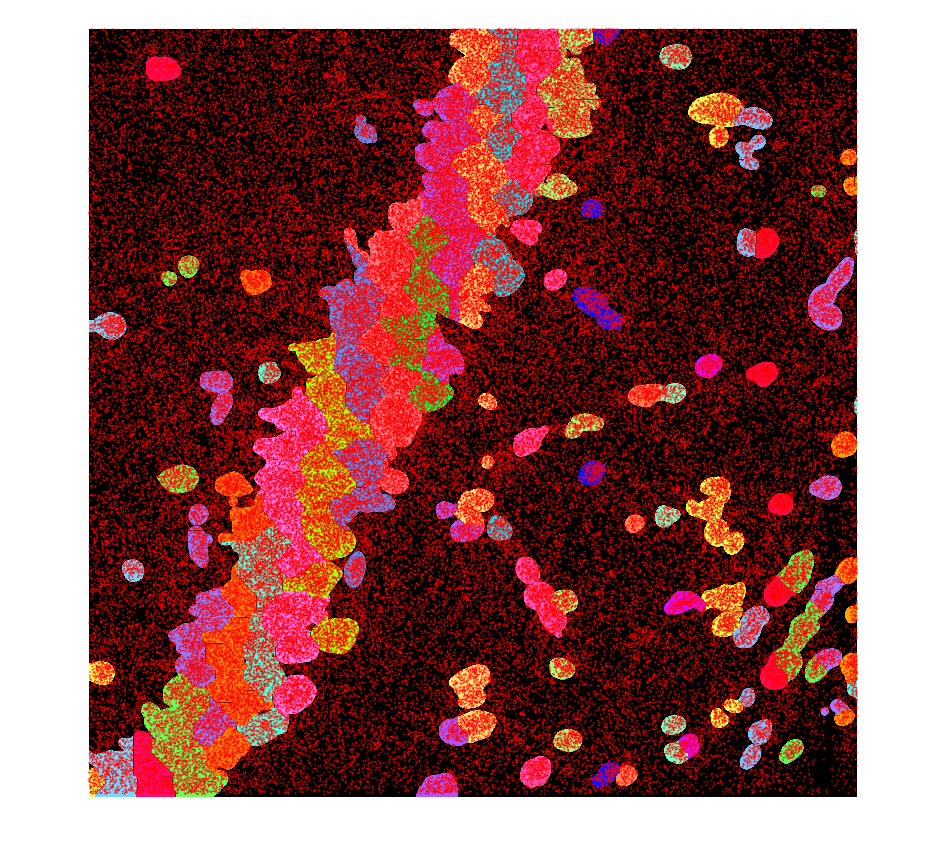

img = imread(fullfile("G:/2021-03-14-mAD-comparison/AD_mouse9494/output/tile_4/tile_4_labeled_cells_line_color.tif"));

plot_centroids(tile_goodSpots, img, 2, 'r')